## 24-774: Lab 1

Due Sept 20

## Team: 

Pranav Narahari

Keitaro Nishimura

Emma Benjaminson

## Notes on Plant Model and Reference: 

Yaw should have amplitude $\pi$/4 rad and freq 0.5 rad/s 

Pitch should have amplitude $\pi$/6 rad and freq 0.4 rad/s

## Preliminaries

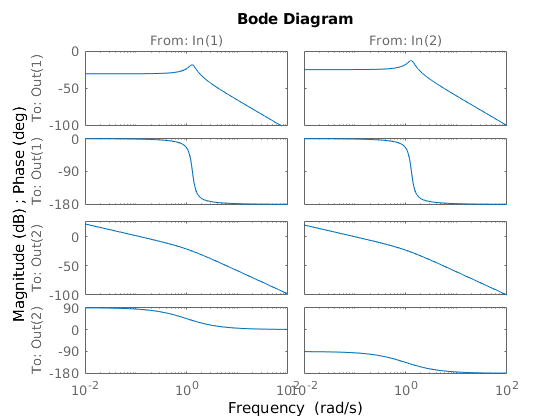

quanser_aero_parameters
quanser_aero_state_space

% nominal plant model 
Gnom = ss(A, B, C, D) ; 
bode(Gnom) ; 

% bodemag(Gnom) ;

The outputs to channel 1 both show typical second order behavior with a resonant peak at about 1.3 rad/s. The output to channel 2 seems to be a proper system with a pole and zero, with first order characteristics. I cannot see anything that I would call "unusual". But I thought that the Bode plots on the diagonals (1,1) and (2,2) would be more similar and the off-diagonal plots would be more chaotic? Why are all the bodes for a particular output (regardless of the input) very similar? --> Maybe its related to coupling somehow?

--> control dominant - one input is stronger than the other

**WHAT ARE CHANNELS 1 AND 2 ON INPUT AND OUTPUT REPRESENTING?**

% saturation nonlinearity to limit control voltages to +/- 25V
Wu = eye(2)*1/25 ; 


## PID Control

See the Lab1_NomPlantModel.slx and Lab1_PIDControllers.slx files for PID controller implementation. 

## Dynamic Decoupling

$G_s = G_D G_M^{-1} G$ where $G_M$ is the plant model (Gnom above). $G_D$ is the diagonal portion of the plant model. $G_M^{-1}$ is a proper, stable approximation of the inverse of the nominal plant model.  (I think the last G in the expression is $G_M$ --> this is correct for the simulation. On the hardware we replace G with the actual plant.) 

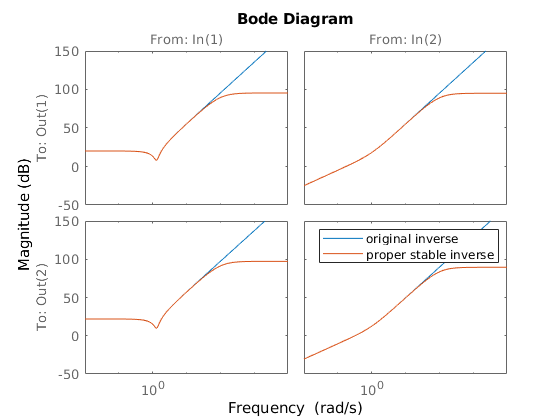

s = tf('s') ; 
Gm = Gnom ; % plant model
Gd = [Gnom(1,1), 0 ; 0 , Gnom(2,2)]; % diagonal portion of plant model

K = 1E2 ; % position of high frequency poles for making inverse a proper tf
Gm_inv = inv(Gnom)*(1/((s/K)+1))^2 ; % writing the extra poles this way ensures they don't affect the DC gain
% Gm_inv = inv(Gnom)*((K/(s+K))^2) ; % proper, stable inverse of plant model

bodemag(inv(Gnom),Gm_inv) ; legend('original inverse', 'proper stable inverse') ; 

Gs = Gd*Gm_inv ; 

The controller output is now very small compared to the reference signals. Why is that happening? Does it have to do with the location of the poles I added to make the inverse plant proper?

See Lab1_DynamicDecoupledPlantModel.slx and Lab1_DynamicDecoupledControllers.slx for this implementation.

## State Space Control

Q = 1 * eye(4) ; 
R = 1 * eye(2) ; 
[K,~,~] = lqr(Gnom,Q,R) ; 